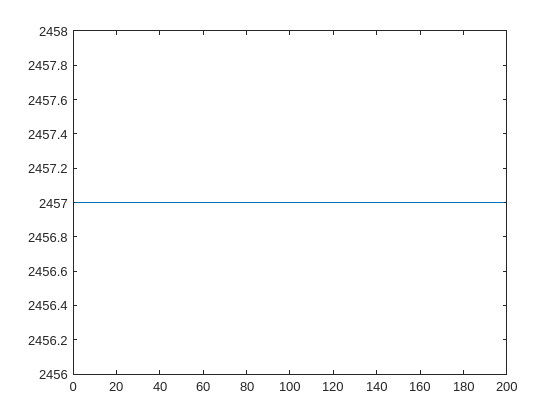


% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["ADC_pan_value", "ADC_tilt_value", "Button_value", "Encoder_tilt_value", "Encoder_pan_value", "Tilt_Velocity"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
joystick = readtable("const_vel_controller.csv", opts);
plot(joystick.ADC_tilt_value)

vel = plot(joystick.Encoder_tilt_value)

vel =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 … ] (1×199 double)
              YData: [285 290 292 299 306 318 326 330 330 331 332 333 342 346 2 27 61 103 135 140 130 109 92 93 109 136 157 164 159 149 145 146 158 167 183 194 197 197 196 196 197 202 208 217 228 239 244 246 246 247 249 256 265 270 280 … ] (1×199 double)

  Show 

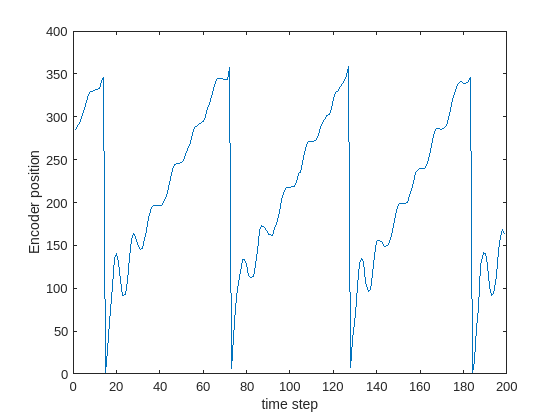

xlabel('time step')
ylabel('Encoder position')
exportgraphics(gcf, 'funny_plot.png')

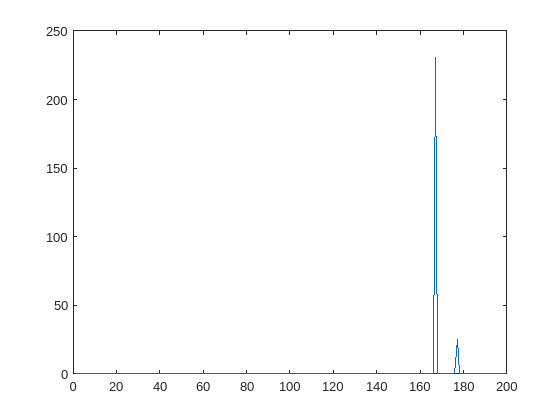

%plot(joystick.Tilt_Velocity./100)
full_forward = readtable("const_vel_100%.csv", opts);
full_backward = readtable("const_vel_0%.csv", opts);
no_controller = readtable("joystick_good.csv", opts);
twenty_forward = readtable("const_vel_60%.csv", opts);
sixty_forward = readtable("const_vel_80%.csv", opts);
twenty_backward = readtable("const_vel_40%.csv",opts);
sixty_backward = readtable("const_vel_20%.csv", opts);
no_controller_sixty = readtable("no_controller_80%.csv",opts);
no_controller_twenty = readtable("no_controller_60%.csv",opts);
no_controller_full = readtable("no_controller_100%.csv",opts);
use_case = readtable("use_case1.csv",opts);
step_resp = readtable("step_0-1.csv", opts);
step2 = readtable("step_0-1-0.csv", opts);
current = readtable("joystick.csv", opts);
plot()
plot(current.Tilt_Velocity)

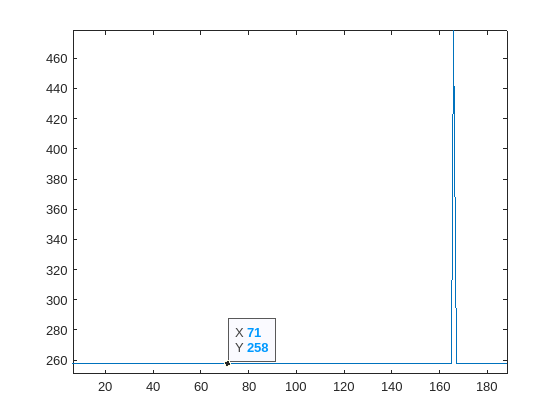

plot(current.Encoder_tilt_value)

t = linspace(0,5,200)

t =          0    0.0251    0.0503    0.0754    0.1005    0.1256    0.1508    0.1759    0.2010    0.2261    0.2513    0.2764    0.3015    0.3266    0.3518    0.3769    0.4020    0.4271    0.4523    0.4774    0.5025    0.5276    0.5528    0.5779    0.6030    0.6281    0.6533    0.6784    0.7035    0.7286    0.7538    0.7789    0.8040    0.8291    0.8543    0.8794    0.9045    0.9296    0.9548    0.9799    1.0050    1.0302    1.0553    1.0804    1.1055    1.1307    1.1558    1.1809    1.2060    1.2312


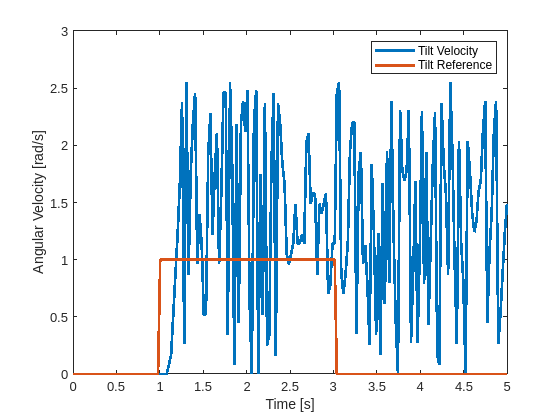



plot(t,step2.Tilt_Velocity./100, LineWidth=2)
hold on 
plot(t,(step2.ADC_tilt_value - (2^12/2)) ./ (2^12/2), LineWidth=2)
legend(["Tilt Velocity", "Tilt Reference"])
xlabel("Time [s]");
ylabel("Angular Velocity [rad/s]")
hold off
exportgraphics(gcf, '../../../Figures/real_step_response.png')

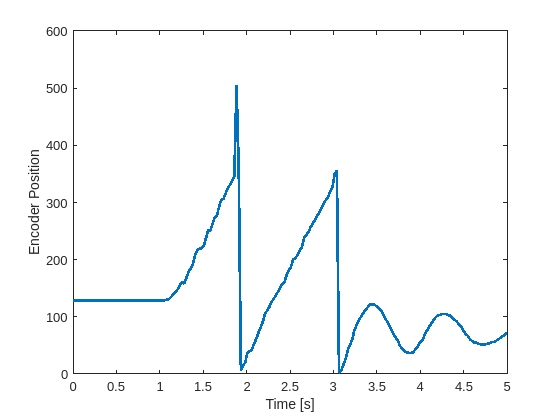

plot(t, step2.Encoder_tilt_value, LineWidth=2)
xlabel("Time [s]");
ylabel("Encoder Position")
exportgraphics(gcf, '../../../Figures/real_step_response_positions.png')

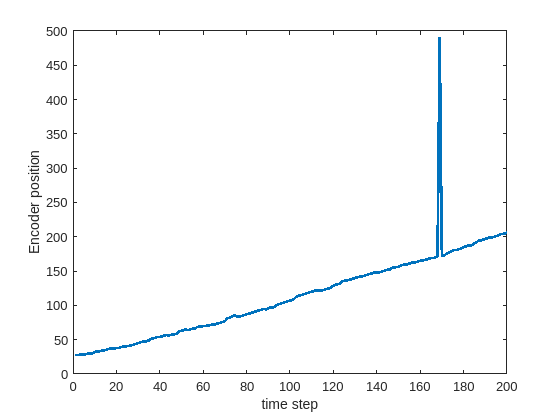

plot(no_controller_twenty.Encoder_tilt_value, LineWidth=2)
xlabel('time step')
ylabel('Encoder position')
exportgraphics(gcf, '../../../Figures/encoder_positions_20.png')

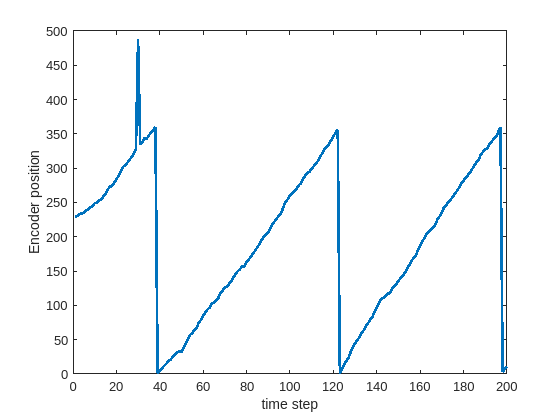

plot(no_controller_sixty.Encoder_tilt_value,LineWidth=2)
xlabel('time step')
ylabel('Encoder position')
exportgraphics(gcf, '../../../Figures/encoder_positions_60.png')

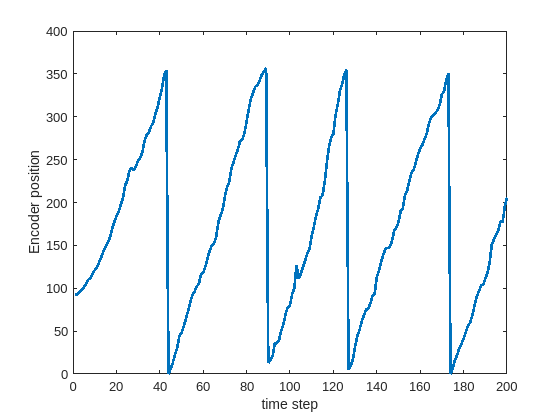


plot(no_controller_full.Encoder_tilt_value, LineWidth=2)
xlabel('time step')
ylabel('Encoder position')
exportgraphics(gcf, '../../../Figures/encoder_positions_100.png')

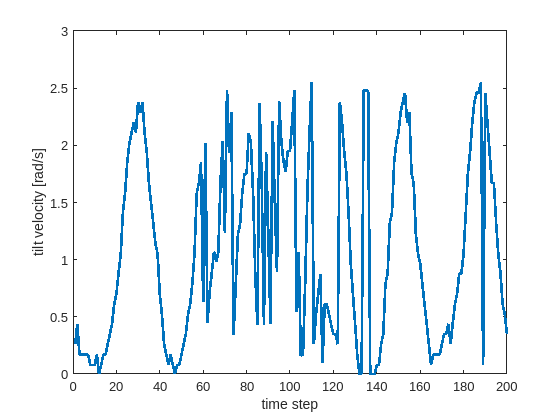


plot(twenty_forward.Tilt_Velocity./100, LineWidth=2)
xlabel('time step')
ylabel('tilt velocity [rad/s]')

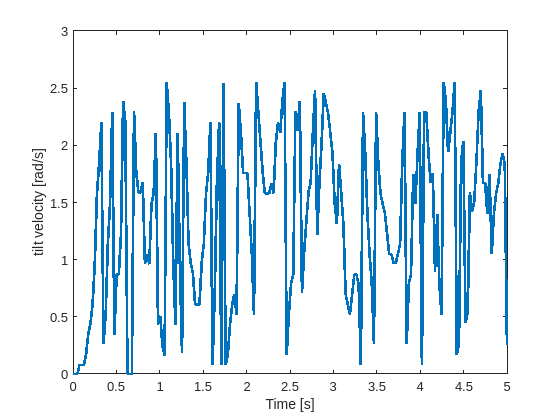

plot(t, sixty_forward.Tilt_Velocity ./ 100, LineWidth=2)
xlabel('Time [s]')
ylabel('tilt velocity [rad/s]')
exportgraphics(gcf, '../../../Figures/60_forward_velocity.png')

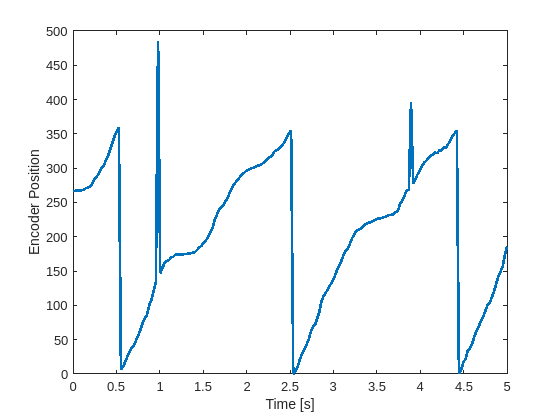

plot(t, sixty_forward.Encoder_tilt_value, LineWidth=2)
xlabel("Time [s]")
ylabel("Encoder Position")
exportgraphics(gcf, '../../../Figures/60_forward_positions.png')

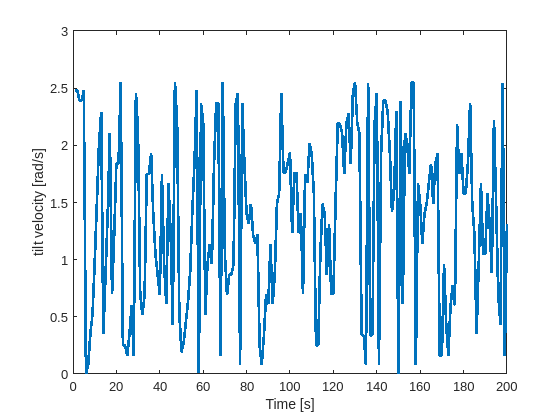


plot(full_forward.Tilt_Velocity ./ 100, LineWidth=2)
xlabel('Time [s]')
ylabel('tilt velocity [rad/s]')
exportgraphics(gcf, '../../../Figures/full_forward_velocity.png')

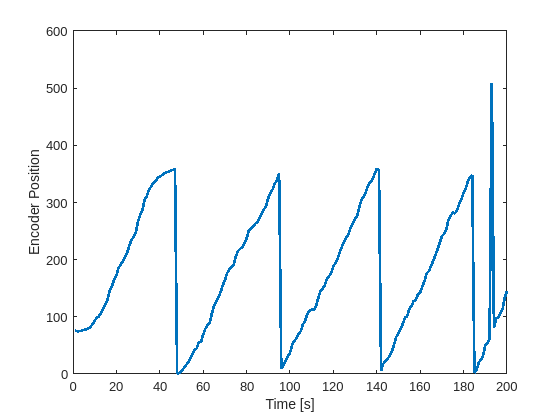

plot(full_forward.Encoder_tilt_value, LineWidth=2)
xlabel("Time [s]")
ylabel("Encoder Position")
exportgraphics(gcf, '../../../Figures/full_forward_positions.png')